clear all; close all; clc;

%Index Number = 10263G
A = 2; B = 6; C = 3;

Filter Variables

t_Ap   = 0.03 +0.01*A ;  %max passband ripple
t_Aa   = 45 + B;         %min stopband attenuation
omg_S  = 2*(100*C +1200);%sampling freqency
omg_P1 = 300 +100*C;     %ower passband edge
omg_P2 = 700 +100*C;     %upper passband edge
omg_A1 = 150 +100*C;     %lower stopband edge
omg_A2 = 800 +100*C;     %upper stopband edge

Filter Parameters

Bt = min(omg_P1-omg_A1, omg_A2-omg_P2);%critical transition width
omg_C1 = omg_P1-Bt/2; % Lower cutoff frequency
omg_C2 = omg_P2+Bt/2; % Upper cutoff frequency

Kaiser Window

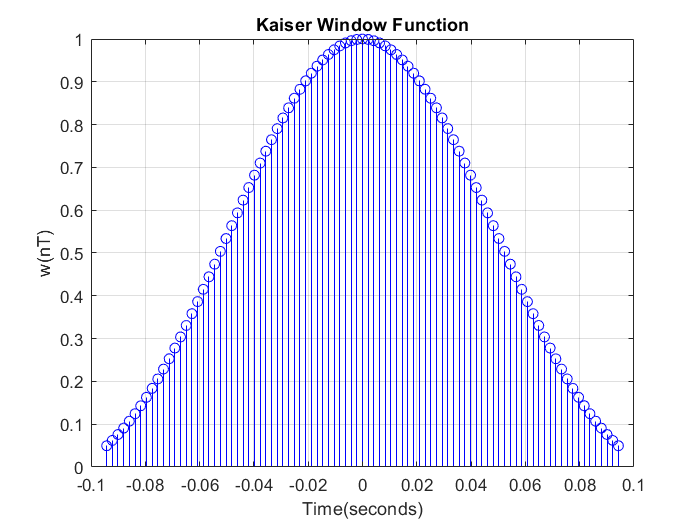

%calculating actual value of Ap
delta_p  = (10^(0.05*t_Ap)-1)/(10^(0.05*t_Ap)+1);
delta_a = 10^(-0.05*t_Aa);
delta  = min(delta_p ,delta_a);
Aa     = -20*log10(delta);

%Calculating value of alpha
if Aa <= 21 
    alpha = 0;
elseif  21 < Aa && Aa <= 50
    alpha = 0.5842*(Aa -21)^0.4-0.07886*(Aa -21);
else
    alpha = 0.1102*(Aa-8.7);
end

%Calculating parameter D
if Aa <= 21 
    D = 0.9222;
else
    D = (Aa - 7.95)/14.36;
end

%Calculating N
Bt = min((omg_P1-omg_A1),(omg_A2-omg_P2));
N = ceil(omg_S*D/Bt + 1);
if mod(N,2) ==0
    N = N+1; 
end

%Determining window function 

T    = 2*pi/omg_S;
n    = floor(-(N-1)/2):1:floor((N-1)/2);
beta = alpha *sqrt(1-(2*n/(N-1)).^2);

wk_nT = getBessel(beta)/getBessel(alpha);

figure;
fig=stem(n*T,wk_nT,'blue');
title('Kaiser Window Function');
xlabel('Time(seconds)');
ylabel('w(nT)');
grid on;

Ideal Impulse Response

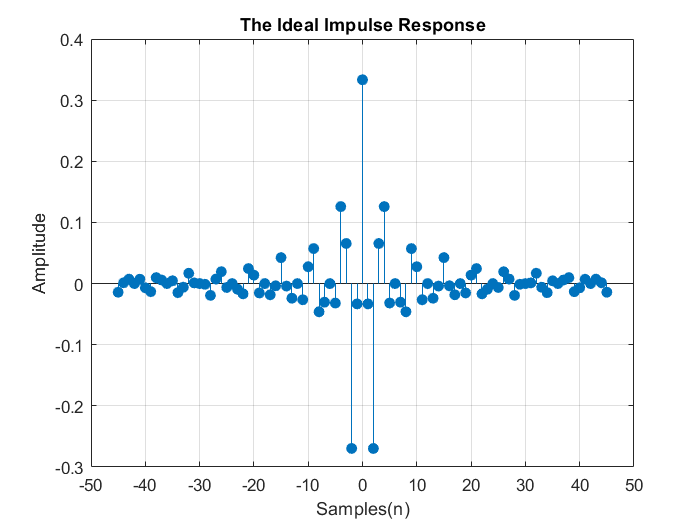

Omega = omg_S*n/(N-1);
omg_C1 = omg_P1 - Bt/2;
omg_C2 = omg_P2 + Bt/2;


H_freq  = zeros(1,length(n));

for j = 1:length(n)
    if Omega(j)<= (-omg_C1) && Omega(j) >= (-omg_C2)
        H_freq(j) =1;
    elseif  (Omega(j))>= omg_C1 && Omega(j) <= (omg_C2)
         H_freq(j) =1;
    end
end
len = length(n);
hd_nT = (sin(omg_C2*n*T) - sin(omg_C1*n*T))./(pi*n); % For each n != 0
hd_nT((N+1)/2) = (omg_C2 - omg_C1)*(2/omg_S); 

figure
stem(n,hd_nT,'filled');
title('The Ideal Impulse Response');
xlabel('Samples(n)');
ylabel('Amplitude');
grid on

Anti-Causal Finite Impulse Response of the Filter

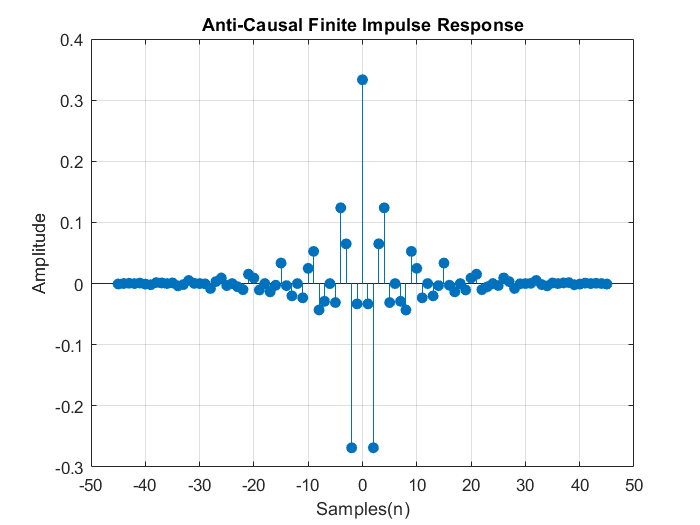

figure;
h_nT = hd_nT.*wk_nT; 
stem(n,h_nT,'filled');
title('Anti-Causal Finite Impulse Response')
xlabel('Samples(n)');
ylabel('Amplitude');
grid on

Causal Finite Impulse Response

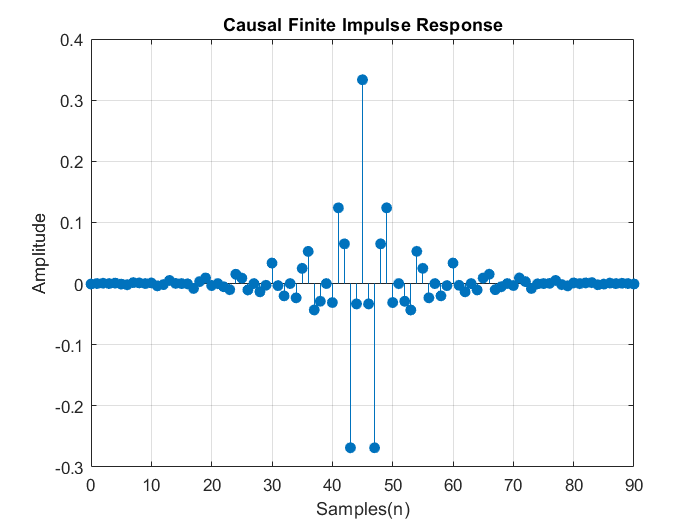

figure;
n_causal = 0:1:N-1; 
stem(n_causal,h_nT,'filled');
xlim([0 N-1]);
title('Causal Finite Impulse Response')
xlabel('Samples(n)');
ylabel('Amplitude');
grid on;

Frequency Response of the Filter

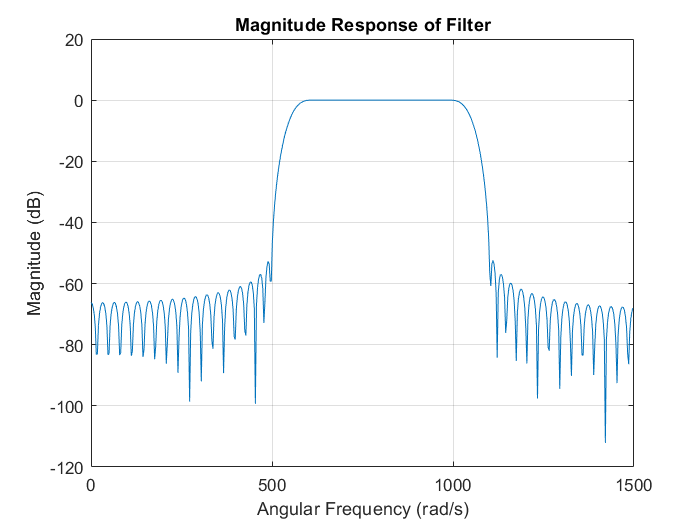

figure;
[H_ejomegaT, omega] = freqz(h_nT);
omega = (omega/pi)*(omg_S/2);         
magnitude = 20*log10(abs(H_ejomegaT));  
plot(omega, magnitude);
xlim([0 omg_S/2]);
title('Magnitude Response of Filter')
xlabel('Angular Frequency (rad/s)');
ylabel('Magnitude (dB)');
grid on;

In the Pass Band

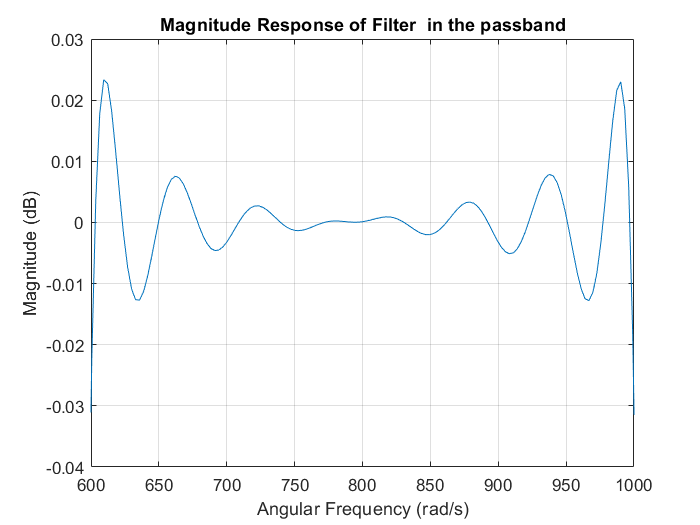

figure;
plot(omega, magnitude);
xlim([omg_P1 omg_P2]); 
title('Magnitude Response of Filter');
xlabel('Angular Frequency (rad/s)');
ylabel('Magnitude (dB)');
grid on;

Input Signal Generation

w1 = omg_A1/2;
w2 = (omg_P1+omg_P2)/2;
w3 = (omg_A2+omg_S/2)/2;
samples=1000;
n1 = 0:1:samples;   % Discrete Values for sampling
n2 = 0:0.01:samples;% Near Continuous values for envelope drawing

x_nT = sin(w1*n1*T) +  sin(w2*n1*T) +sin(w3*n1*T);
x_t  = sin(w1*n2*T) +  sin(w2*n2*T) +sin(w3*n2*T); 
X_Omega=fft(x_nT,omg_S/2);

Input Signal in Time Domain

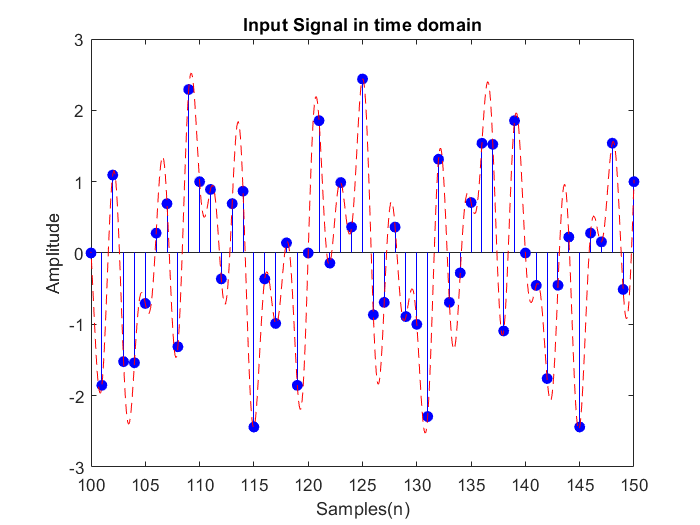

figure;
stem(n1, x_nT,'filled', 'b');
title('Input Signal in time domain');
xlabel('Samples(n)');
ylabel('Amplitude');
hold on;
plot(n2, x_t,'--','Color','r');xlim([100 150])

Input Signal in Frequency Domain

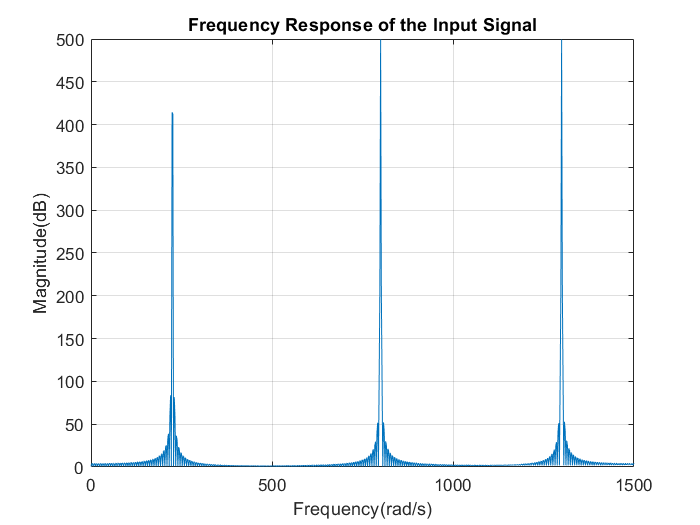

figure;
plot(0:2:1800,abs(X_Omega(1:901)));
title('Frequency Response of the Input Signal');
ylabel('Magnitude(dB)');
xlabel('Frequency(rad/s)');
xlim([0 1500]);
grid on

Output of the Ideal Filter

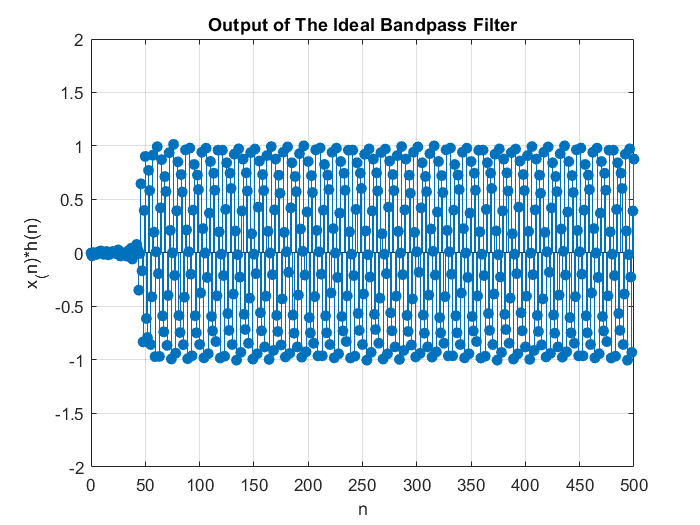

H_Fil=fft(h_nT,omg_S/2);
Y_Omega=X_Omega.*H_Fil;
y_n=ifft(Y_Omega);

H_Fil=fft(hd_nT,omg_S/2);
Y_Out=X_Omega.*H_Fil;
y_out=ifft(Y_Out);


figure;
stem(0:500,y_out(1:501),'filled');
title('Output of The Ideal Bandpass Filter');
xlabel('n'); ylabel('x_(n)*h(n)');
ylim([-2 2]);
grid on;

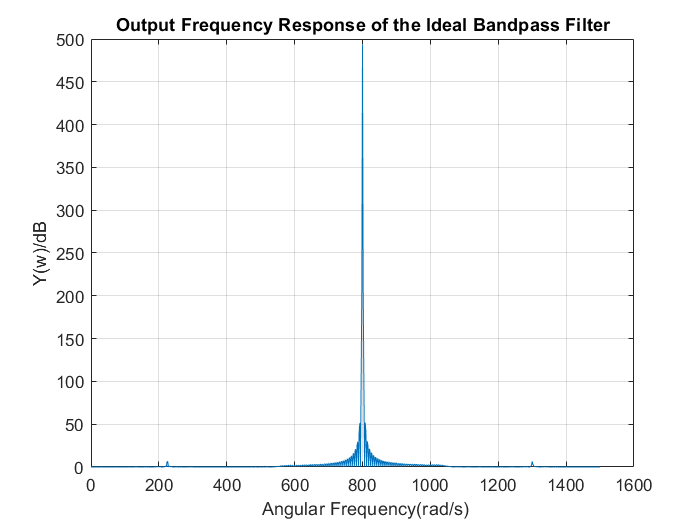


figure;
plot(0:2:1500,abs(Y_Out(1:751)));
title('Output Frequency Response of the Ideal Bandpass Filter');
ylabel('Y(w)/dB');xlabel(' Angular Frequency(rad/s)');xlim([0 1600]);
grid on;

Output of the Filter Implemented

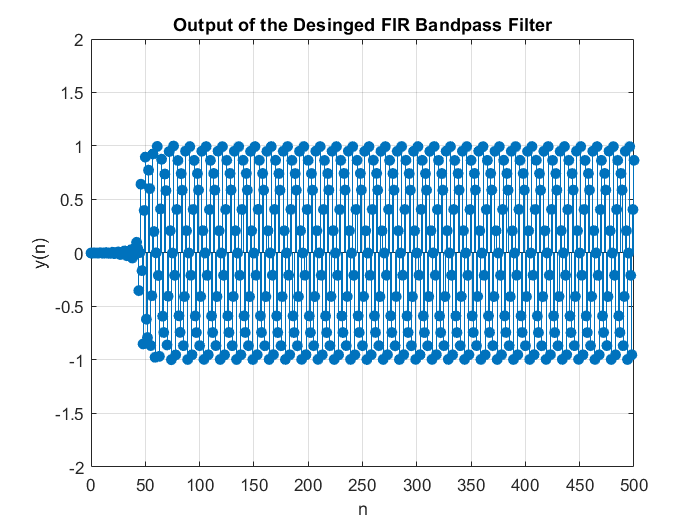

figure;
stem(0:1:500,y_n(1:501),'filled');
title('Output of the Desinged FIR Bandpass Filter');
xlabel('n'),ylabel('y(n)');
ylim([-2 2]);
grid on

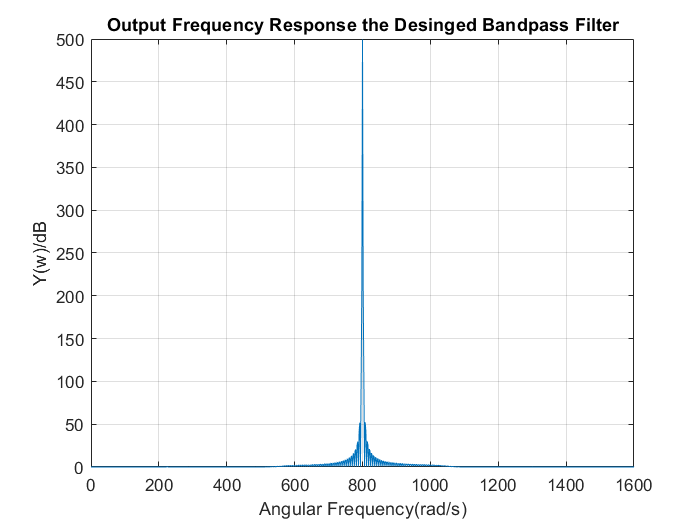


figure;;
plot(0:2:1800,abs(Y_Omega(1:901)));
title('Output Frequency Response the Desinged Bandpass Filter');
ylabel('Y(w)/dB');xlabel('Angular Frequency(rad/s)');xlim([0 1600]);
grid on

Bessel Function

function [Ix] = getBessel(x)% k is considered as 500
sum=1;
for k=1:500
    sum=sum+((1/factorial(k))*(x/2).^k).^2;
end
Ix=sum;
end
